# Wireless Systems Project

## Task 1

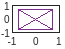

%%% Given 
clear all
M = 16;
N = 4;
L = 5;
h = transpose([0.227, 0.46, 0.688, 0.46, 0.227]);
CP = L-1;
ZP = 2*(L-1);
d_start_CP = zeros(M, N);   % Represents d in matrix form
d_final_CP = zeros(M, N);
d_start_ZP = zeros(M, N);   
d_final_ZP = zeros(M, N);

for n = 1:1:N
%%% Cyclic Prefix
%%% Step 1
    symbMap = (1/sqrt(2)).*[1+1j, -1+1j, -1-1j, 1-1j];  % QPSK
    d_tilda1 = symbMap(round(3*rand([1 M]))+1);  % Get random sqrt(2) values
    d_start_CP(:, n) = d_tilda1; % transpose QPSK row onto column
end

plot(d_start_CP)

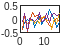


%%% Step 2
% the ifft calculates each column
%  individually as a sequnce
d_time = ifft(d_start_CP); % freq -> time, for each column of QSPK symbols

plot(real(d_time))

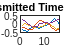


%%% Step 3
% puts symbols s(l)=13, 14, 15, 16
%  aka symbols x(l)=17, 18, 19, 20
%  at the start of each 
%  20 symbol vector column
x = zeros(M+CP, N); % Cyclic Prefix of last "L-1" d values
for j = 1:1:CP
    for c = 1:1:N
        x(j, c) = d_time(j+M-CP, c);
    end
end

% Load data into the rest of x
% into respective columns
for j = 1:1:M
    for c = 1:1:N
        x(j+CP, c) = d_time(j, c);
    end
end

%%% Step 4
y1 = zeros(M, N);
for m = L:1:M+CP    % Transmission y = h*x
    for j = 1:1:length(h)
        for c = 1:1:N
            y1(m-CP, c) = y1(m-CP, c) + h(j)*x(m-j+1, c);
        end
    end
end

plot(real(y1))
title('Transmitted Time Domian');

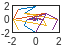


%%% Step 5
y_tilda = fft(y1);
plot(y_tilda)


%%% Step 6
for n = 1:1:N
    h_tilda = fft(h, 16); % extends h to be 16 values long
    d_tilda2 = y_tilda./h_tilda;
    d_final_CP(:, n) = d_tilda2(:, n);
end 

% d_final_CP is the recovered 
% OFDM QPSK symbols after 
% recovering from time domain 
% transmission, no carrier or
% subcarrier modulation
d_final_CP;

%%% Zero Padded
for kk = 1:1:N
%%% Step 1
    symbMap = (1/sqrt(2)).*[1+1j, -1+1j, -1-1j, 1-1j];  % QPSK
    d_tilda1 = symbMap(round(3*rand([1 M]))+1);  % Get random sqrt(2) values
    d_start_ZP(:, kk) = d_tilda1;
end
%%% Step 2
d_time = ifft(d_start_ZP); % freq -> time

%%% Step 3
x = zeros(M+ZP, N); % Zero Padding of first/last "L-1" d values

for j = 1:1:M   % Load data into the rest of x
    for c = 1:1:N
        x(j+CP, c) = d_time(j, c);
    end
end

%%% Step 4
%y2 = zeros(M+CP, 1);
y2 = zeros(M+CP, N);
for m = L:1:M+ZP    % Transmission y = h*x
    for jj = 1:1:length(h)
        for c = 1:1:N
            y2(m-CP, c) = y2(m-CP, c) + h(jj)*x(m-jj+1, c);
        end
    end
end
y2;
% for m = L:1:M+CP    % Transmission y = h*x
%     for jj = 1:1:length(h)
%         y2(m-CP, 1) = y2(m-CP, 1) + h(jj)*x2(m-jj+1, 1);
%     end
% end

% %%% Step 5
y_tilda = zeros(M, N);
for i = 1:1:M
    for k = 1:1:M+CP
        for c = 1:1:N
            y_tilda(i, c) = y_tilda(i, c) + y2(k, c)*exp(-1i*2*pi*(k-1)*(i-1)/M);
        end
    end
end
y_tilda;
% % %%% Step 6
for n = 1:1:N
    h_tilda = fft(h, 16);
    d_tilda2 = y_tilda./h_tilda;
    d_final_ZP(:, n) = d_tilda2(:, n);
end
d_final_ZP;


## Task 2

D = 200;
W = 1;
K = 2048;
x2 = zeros(K, 1);
CP = 200;


%%% Cyclic Prefix
%%% Step 1
symbMap = (1/sqrt(2)).*[1+1j, -1+1j, -1-1j, 1-1j];  % QPSK
d_tilda1 = symbMap(round(3*rand([1 K]))+1);  % Get random sqrt(2) values
   % d_start_CP(:, n) = d_tilda1;


%%% Step 2
d_time = ifft(d_tilda1); % freq -> time

%%% Step 3
x = zeros(K+CP, W);



x2 = [zeros(1, D), d_time, zeros(1, D)];


%x2 = transpose(x2);

%%% Step 3: Concatenation
% xbar = zeros(1, W*(D+K) + D);
% 
% for c = 1:1:W
%     xbar(1, (c*D+(c-1)*(K)+1) : c*D+c*(K)) = x2(c, :);
% end
xbar = x2;
%%% Step 4: Insert 0
lambda = 24;
xbar_ovf = zeros(1, (W*(D+K)+D) * lambda);
for i = 1:1:length(xbar_ovf)
    if mod(i, lambda) == 0 
        xbar_ovf(1, i) = xbar(1, i/lambda);
    else
        xbar_ovf(1, i) = 0;
    end
end


%%% Step 5: rcosdesign
beta = .125; % roll-off factor
Fs = 192000; % sampling frequency
Fd = 8000; % data/transfer rate
lamda_oversamp = Fs/Fd;
delay = 100;
span = 2*delay;
Rn = rcosdesign(beta, span, Fs/Fd, 'sqrt');

% uncomment next line to see plot of values
% fvtool(Rn,'Analysis','Impulse')

 Xtilda_BB = conv(xbar_ovf, Rn)
% plot(real(xbar_ovf))
% plot(real(Xtilda_BB))
% title('Xtilda')

%%% Step 6: Baseband to Passband
fc = 24000; % Carrier Frequency
Bw = 8000; % Bandwidth
k = 2048; % number of subcarriers
delta_f = Bw/k; % subcarrier spacing = 3.91Hz
Ts = 1/Bw; % sampling time?
T = 1/delta_f; % useful time
tt = T / lamda_oversamp;
Tg = 0.025; % in secs (OFDM symbol guard Time?)
tg = Tg / lamda_oversamp;
ts = (Ts/lamda_oversamp); 
X_PB = zeros(1, length(Xtilda_BB));

for n = 1:1:length(Xtilda_BB)
    X_PB(1, n) = real(Xtilda_BB(1, n)*exp(1i*2*pi*fc*(n-1)*(ts)));
end


% Step 7 - Add LFM ambles to OFDM burst
Tschirp = 1/Fs;
t1 = .05;
t = (0:Tschirp:t1);
f0 = fc-4000;
f1 = fc+4000;
Beta = (f1-f0)/t1;
ft = f0 + Beta.*t;

LFM_chirp = cos(2*pi*ft.*t);
plot(real(LFM_chirp))
LFM_zeros = zeros(1, .2/Tschirp);

LFM = [LFM_chirp,LFM_zeros,LFM_chirp,LFM_zeros,LFM_chirp,LFM_zeros,LFM_chirp,LFM_zeros];

X_PB_LFM = [LFM,X_PB,LFM];

plot(X_PB_LFM);

% Step 8 - Validation
X_Tilda_BB_I = zeros(1, length(X_PB));
X_Tilda_BB_Q = zeros(1, length(X_PB));
X_Tilda_BB = zeros(1, length(X_PB));

for n = 1:1:length(X_PB)
    X_Tilda_BB_I(1,n) = X_PB(1, n)*2*cos(2*pi*fc*(n-1)*ts); 
end

for n = 1:1:length(X_PB)
    X_Tilda_BB_Q(1, n) = -X_PB(1, n)*2*sin(2*pi*fc*(n-1)*ts);
end

for n = 1:1:length(X_PB)
    X_Tilda_BB(1, n) = X_Tilda_BB_I(1, n) + 1i*X_Tilda_BB_Q(1, n);
end
X_PB;
X_Tilda_BB;
n0 = 4824;
%X_Bar_ovf = zeros(1, length(X_Tilda_BB));
X_Bar_ovf = conv(X_Tilda_BB, Rn);
%plot(X_Bar_ovf);
%plot(real(Xtilda_BB))
%plot(real(X_Tilda_BB))
X = [];
%X = zeros(1, length(X_Bar_ovf));

for n = 1:1:length(X_Tilda_BB)/lambda
   X = [X, X_Bar_ovf(1, (n-1)*lambda + n0)];
end
X = X(201:length(X)-D);
%plot(real(X));
Yfr = zeros(1, K+D);
for n = 1:1:K+D
    for k = 1:1:K+D
        for w = 1:1:W
            Yfr(w, n) = Yfr(w, n) + X(w, k)*exp(-1i*2*pi*(k-1)*(n-1)/K);
        end
    end
end
